clear;close all;clc;

% Exercise 1-1 
a = (4.*7 - 8) / (3^4 -1)

a = 0.2500

b = exp((sin(3.2)))

b = 0.9433

c = (5 + log(37/2.9.*1.7)) / 9

c = 0.8974

% Exercise 1-2
A = [3 5 1;2 0 1;-1 1 0];
B = [-2,1,-4]';
C = inv(A) *B

C =     2.8333
   -1.1667
   -4.6667


% Exercise 1-3
L1 = (-3:0.1:5)

L1 =    -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000


% Exercise 1-4
L2 = 10 .^ (-3:1:5)

L2 = 1.0e+05 *

    0.0000    0.0000    0.0000    0.0000    0.0001    0.0010    0.0100    0.1000    1.0000


% Exercise 1-5
syms k 
symsum(k.*(101-k),1,100)

$$ans = 171700$$

u = 1:100;          
v = 100:-1:1;      
u * v'

ans = 171700

% Exercise 1-6
A = rand(5,6);
B = A(A > 0.3 & A < 0.7)

B =     0.6948
    0.3171
    0.4387
    0.3816
    0.4898
    0.4456
    0.6463
    0.6797
    0.6551
    0.4984


% Exercise 1-7
A = zeros(4,4);
B = ones(4,3);
C = cat(2,A,B)

C =      0     0     0     0     1     1     1
     0     0     0     0     1     1     1
     0     0     0     0     1     1     1
     0     0     0     0     1     1     1


% Exercise 1-8
A = [3 2 0; -5 6 1; 1 0 2];
index = find(A)

index =      1
     2
     3
     4
     5
     8
     9


[row,col] = find(A == 0 )

row =      3
     1


col =      2
     3


% Exercise 1-9
A = [1 25 7 20; 8 90 30 18; 
    12 23 15 176; 50 0 31 9];
col = [1;0;2;8];
A = [A col]

A =      1    25     7    20     1
     8    90    30    18     0
    12    23    15   176     2
    50     0    31     9     8


[r,c] = size(A);
r+c

ans = 9

B = A(2:4,1:2:5)

B =      8    30     0
    12    15     2
    50    31     8


c = A;
c(2:2:4,:)

ans =      8    90    30    18     0
    50     0    31     9     8


A = reshape(A,[5,4])

A =      1    90    15     9
     8    23    31     1
    12     0    20     0
    50     7    18     2
    25    30   176     8


mean(A,1)

ans =    19.2000   30.0000   52.0000    4.0000


mean(A,2)

ans =    28.7500
   15.7500
    8.0000
   19.2500
   59.7500


mean(mean(A))

ans = 26.3000

A(1) = nan;
A(end) = nan;
A

A =    NaN    90    15     9
     8    23    31     1
    12     0    20     0
    50     7    18     2
    25    30   176   NaN


mean(mean(A))

ans = NaN

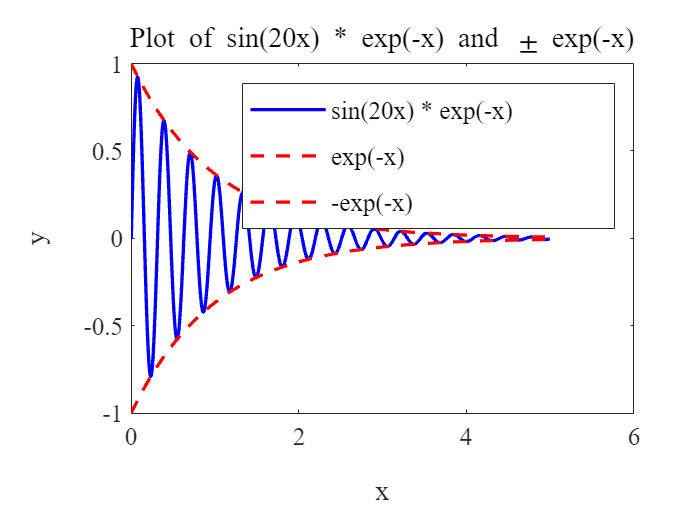

% Exercise 2 
x = linspace(0, 5, 500);        
y1 = sin(20*x) .* exp(-x);      
y2 = exp(-x);                   
y3 = -exp(-x);                 
figure;                         
plot(x, y1, 'b-', 'LineWidth', 2);    
hold on;                        
plot(x, y2, 'r--', 'LineWidth', 2);   
plot(x, y3, 'r--', 'LineWidth', 2);   


title('Plot of sin(20x) * exp(-x) and \pm exp(-x)', 'FontSize', 15, 'FontName', 'Times New Roman');
xlabel('x', 'FontSize', 15, 'FontName', 'Times New Roman');
ylabel('y', 'FontSize', 15, 'FontName', 'Times New Roman');
legend('sin(20x) * exp(-x)', 'exp(-x)', '-exp(-x)', 'FontSize', 15, 'FontName', 'Times New Roman');

set(gca, 'FontSize', 15, 'FontName', 'Times New Roman');

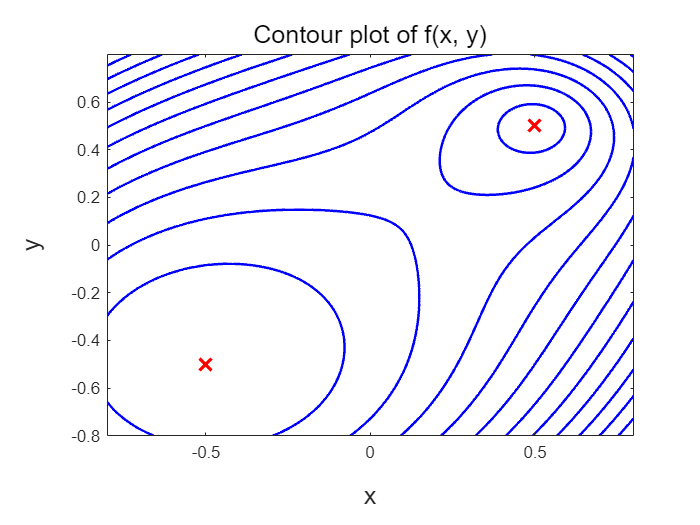

% Exercise 4
x = linspace(-0.8, 0.8, 500);   
y = linspace(-0.8, 0.8, 500);

[X, Y] = meshgrid(x, y);

Z = sqrt((X - 0.5).^2 + (Y - 0.5).^2) .* ((X + 0.5).^2 + (Y + 0.5).^2);
figure;
contour(X, Y, Z, 'LineColor', 'b', 'LineWidth', 1.5);  
hold on;

plot(0.5, 0.5, 'rx', 'MarkerSize', 10, 'LineWidth', 2);   
plot(-0.5, -0.5, 'rx', 'MarkerSize', 10, 'LineWidth', 2);

xlabel('x', 'FontSize', 15);
ylabel('y', 'FontSize', 15);
title('Contour plot of f(x, y)', 'FontSize', 15);

hold off;

%Exercise 3

function result = Cal_Euclidean(u,v)
    for i = 1:length(u)
        results  = results + (u(i)-v(i))^2;
    end
    result = sqrt(results);
end